%% TORPEDO LADLE CAR (TLC) TILTING FEASIBILITY ANALYSIS
% Description:
%   Calculates safe tilt angle, tipping risk, actuator force, and
%   hydraulic pressure for TLC tilt control feasibility.
%   Units: SI (m, kg, Pa, rad, N)

clc; 
clear; 
close all;

%% -------------------- INPUT PARAMETERS --------------------
% Mass properties
m_metal   = 280000;    % kg  (molten metal)
m_torpedo = 70000;     % kg  (empty ladle car)
M_total   = m_metal + m_torpedo;   % total mass (kg)

% Geometry
b_support = 2.5;       % m  (half base width of support)
h_cg      = 1.8;       % m  (vertical CG above trunnion)
r_cg      = 1.2;       % m  (horizontal CG distance from trunnion)
L_lever   = 3.0;       % m  (effective actuator lever arm)

% Hydraulic parameters
A_piston  = 0.20;      % m^2 (effective piston area)
p_limit   = 350e5;     % Pa  (max safe hydraulic pressure, e.g., 350 bar)

% Constants
g = 9.81;              % m/s^2

%% -------------------- COMPUTATIONS --------------------

% 1. Safe geometric tipping angle
theta_max = atan(b_support / h_cg);      % radians
theta_max_deg = rad2deg(theta_max);

% 2. Define angle sweep for plotting
theta = linspace(0, theta_max, 200);     % radians

% 3. Compute torque, force, and pressure vs. angle
M_tilt = M_total * g * r_cg .* sin(theta);        % N·m
F_act  = M_tilt ./ L_lever;                       % N
p_req  = F_act ./ A_piston;                       % Pa

% 4. Define safety thresholds (Amber = 80%, Red = 95%)
theta_amber = 0.8 * theta_max;
theta_red   = 0.95 * theta_max;

%% -------------------- RESULTS SUMMARY --------------------
fprintf('--- TLC TILTING FEASIBILITY RESULTS ---\n');

--- TLC TILTING FEASIBILITY RESULTS ---


fprintf('Total Mass: %.0f kg\n', M_total);

Total Mass: 350000 kg


fprintf('Safe Tipping Angle (theoretical): %.2f deg\n', theta_max_deg);

Safe Tipping Angle (theoretical): 54.25 deg


fprintf('Amber Warning Angle: %.2f deg\n', rad2deg(theta_amber));

Amber Warning Angle: 43.40 deg


fprintf('Red Lock Angle: %.2f deg\n', rad2deg(theta_red));

Red Lock Angle: 51.53 deg


fprintf('Peak Required Pressure: %.1f bar\n', max(p_req)/1e5);

Peak Required Pressure: 55.7 bar



if max(p_req) < p_limit
    fprintf('✅ Feasible: Required pressure < %.0f bar limit.\n', p_limit/1e5);
else
    fprintf('⚠️  Not Feasible: Required pressure exceeds %.0f bar limit.\n', p_limit/1e5);
end

✅ Feasible: Required pressure < 350 bar limit.


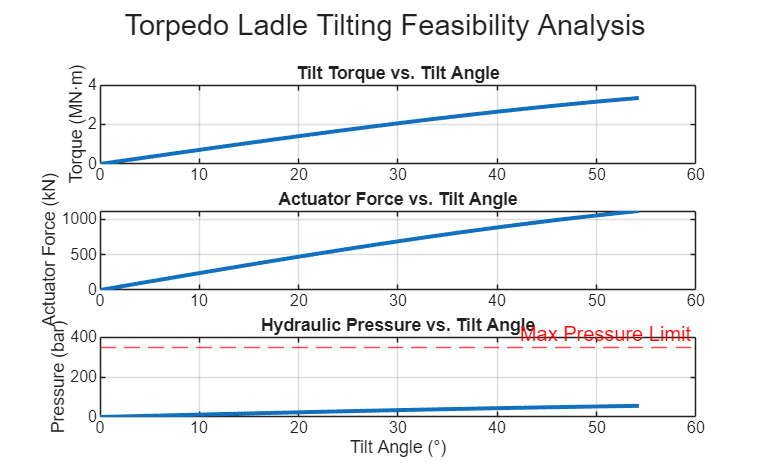


%% -------------------- PLOTS --------------------
figure('Name','TLC Tilt Feasibility','NumberTitle','off');

subplot(3,1,1)
plot(rad2deg(theta), M_tilt/1e6, 'LineWidth',2)
ylabel('Torque (MN·m)')
grid on
title('Tilt Torque vs. Tilt Angle')

subplot(3,1,2)
plot(rad2deg(theta), F_act/1e3, 'LineWidth',2)
ylabel('Actuator Force (kN)')
grid on
title('Actuator Force vs. Tilt Angle')

subplot(3,1,3)
plot(rad2deg(theta), p_req/1e5, 'LineWidth',2)
yline(p_limit/1e5,'r--','Max Pressure Limit');
ylabel('Pressure (bar)')
xlabel('Tilt Angle (°)')
grid on
title('Hydraulic Pressure vs. Tilt Angle')

sgtitle('Torpedo Ladle Tilting Feasibility Analysis')


%% -------------------- END --------------------
